# Unit 4.4: 2nd-Order LP Butterworth responses

Prepared for EG-247 Signals and Systems by Dr Chris P. Jobling

## **Butterworth low-pass filter**

N-th Order Butterworth Filter


$$$$\left| H_B(\omega ) \right| = \frac{1}{\left(1 + \left(\frac{\omega }{\omega _c}\right)^{2N}\right)^{\frac{1}{2}}}$$$$


**Remarks**

- DC gain is $\left|H\_B\left(\textrm{j0}\right)\right|=1$

- Attenuation at the cut-off frequency is $|H_B(j\omega_c)|=1/\sqrt{2}$ for any $N$

More about the Butterworth filter: [Wikipedia Article](https://en.wikipedia.org/wiki/Butterworth_filter).

## **Example 5: Second-order BW Filter**

Example The second-order butterworth Filter is defined by Characteristic Equation (CE):


$$p(s) = s^2 + \omega_c\sqrt{2}s+\omega_c^2 = 0$$


Calculate the roots of $p(s)$ (the poles of the filter transfer function) in both Cartesian and polar form.

wc = 100;
% Transfer function
H = tf(wc^2,[1, wc*sqrt(2), wc^2])

H =
 
          10000
  ---------------------
  s^2 + 141.4 s + 10000
 
Continuous-time transfer function.
Model Properties


Poles of the filter

[poles] = pole(H)

poles = -70.710678118654755 +70.710678118654755i
-70.710678118654755 -70.710678118654755i


Natural frequency $\omega_n$ and damping ratio $\zeta$ of the poles

[wn,zeta] = damp(H)

wn =    100
   100


zeta =    0.707106781186548
   0.707106781186548


Phase of the poles

angle(poles)*180/pi

ans =    135
  -135


### Example 8

Determine the impulse and sterp response of a Butterworth low-pass filter

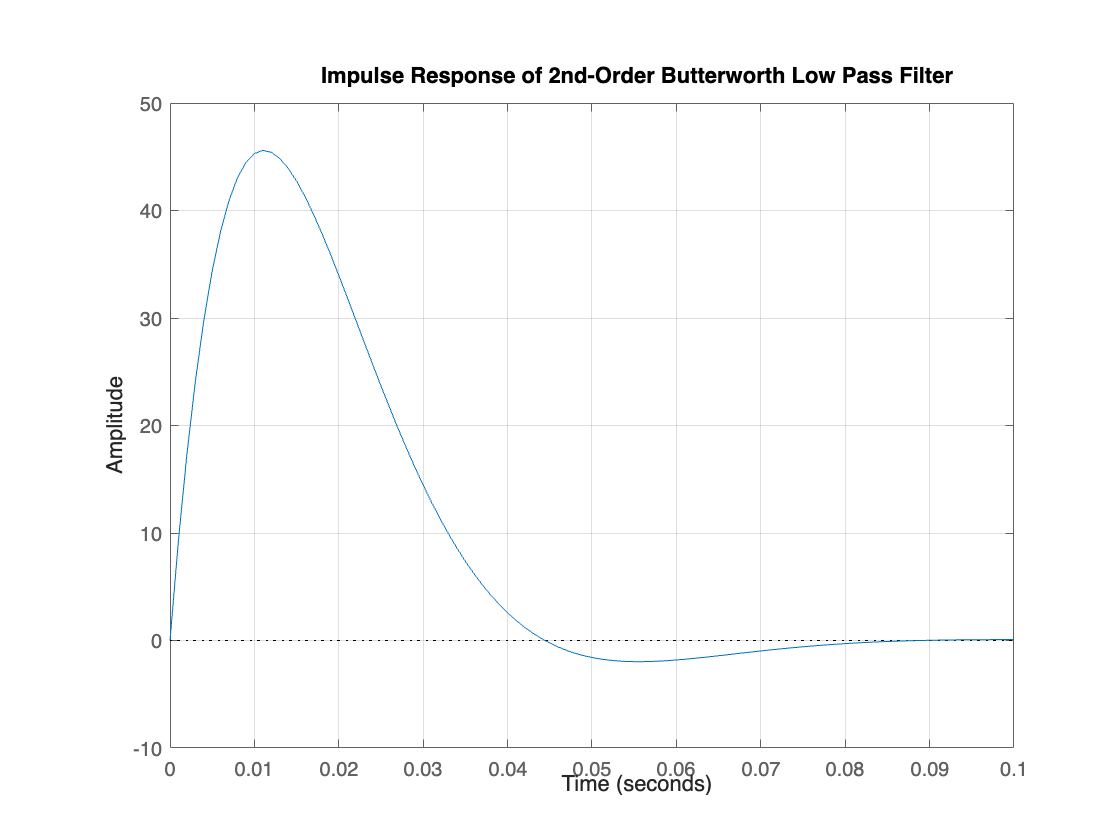

impulse(H,0.1)
grid
title('Impulse Response of 2nd-Order Butterworth Low Pass Filter')

### Magnitude frequency response

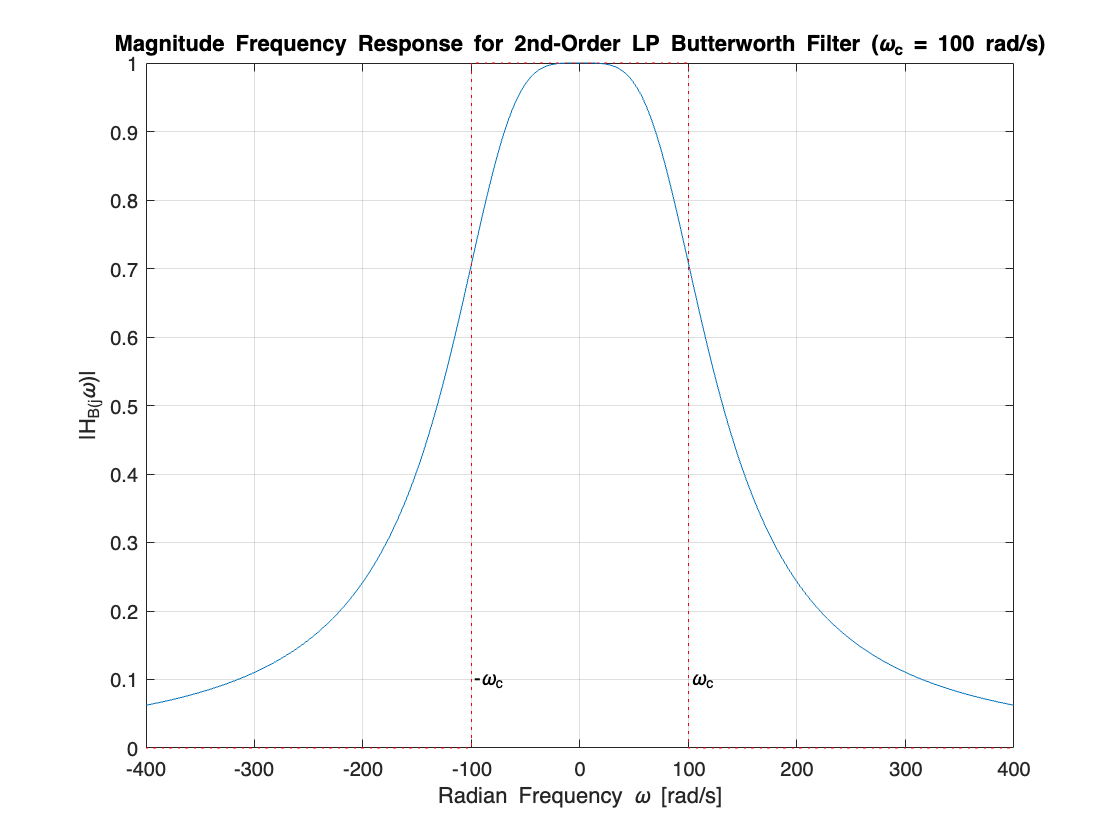

figure
w = -400:400;
mHlp = 1./(sqrt(1 + (w./wc).^4));
plot(w,mHlp)
grid
ylabel('|H_B(j\omega)|')
title('Magnitude Frequency Response for 2nd-Order LP Butterworth Filter (\omega_c = 100 rad/s)')
xlabel('Radian Frequency \omega [rad/s]')
text(100,0.1,'\omega_c')
text(-100,0.1,'-\omega_c')
hold on
plot([-400,-100,-100,100,100,400],[0,0,1,1,0,0],'r:')
hold off

### Bode plot

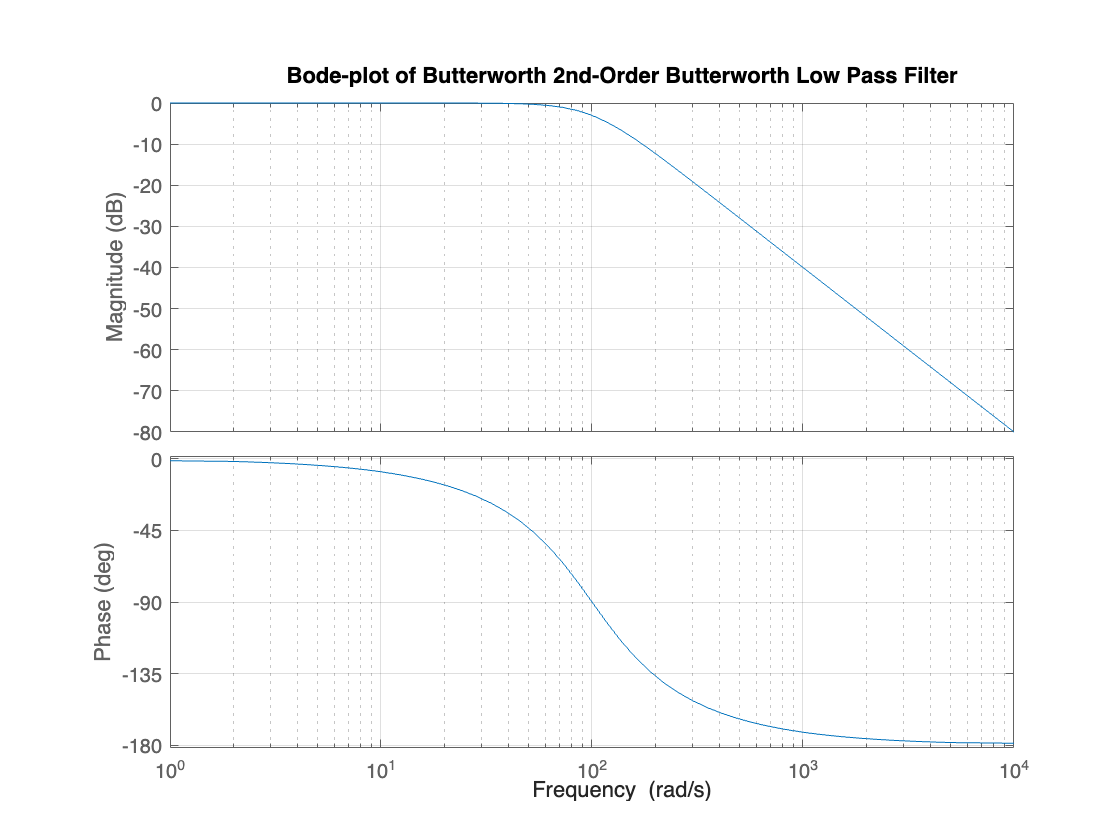

figure
bode(H)
grid
title('Bode-plot of Butterworth 2nd-Order Butterworth Low Pass Filter')

### Step response

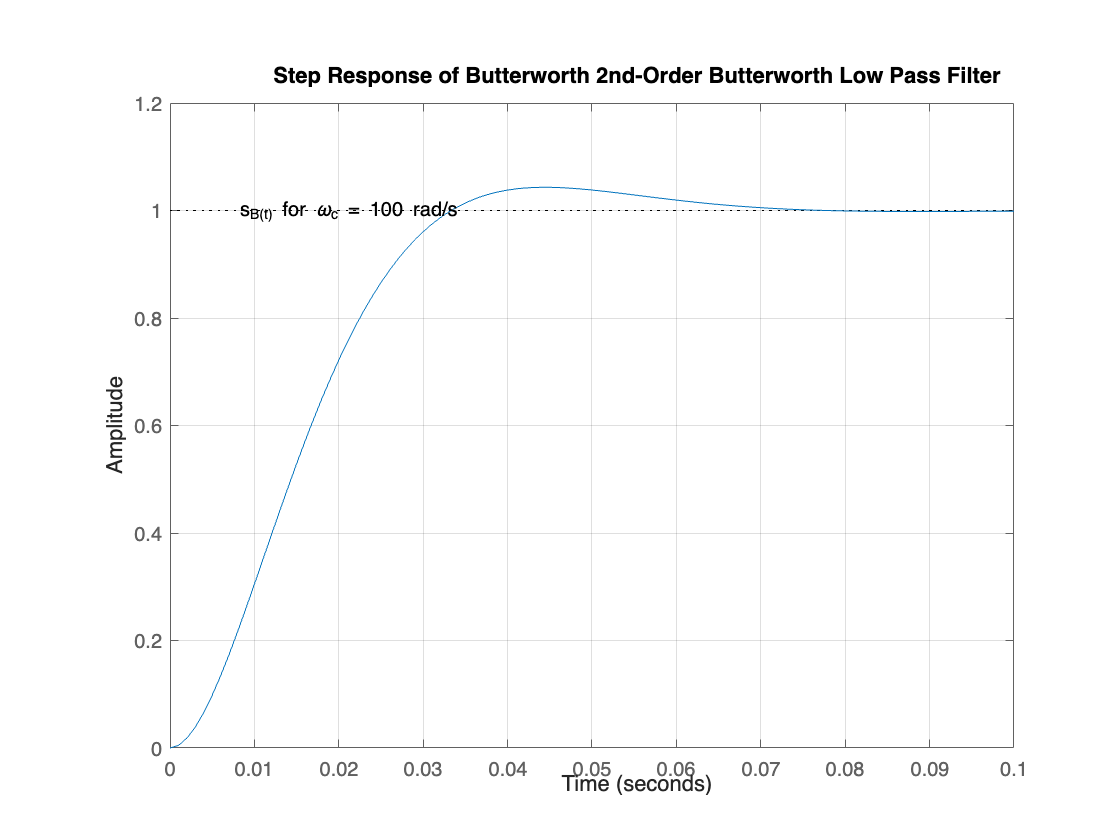

figure
step(H,0.1)
title('Step Response of Butterworth 2nd-Order Butterworth Low Pass Filter')
grid
text(0.008,1,'s_B(t) for \omega_c = 100 rad/s')

## High-pass filter

figure
Hhp = 1 - H

Hhp =
 
      s^2 + 141.4 s
  ---------------------
  s^2 + 141.4 s + 10000
 
Continuous-time transfer function.
Model Properties


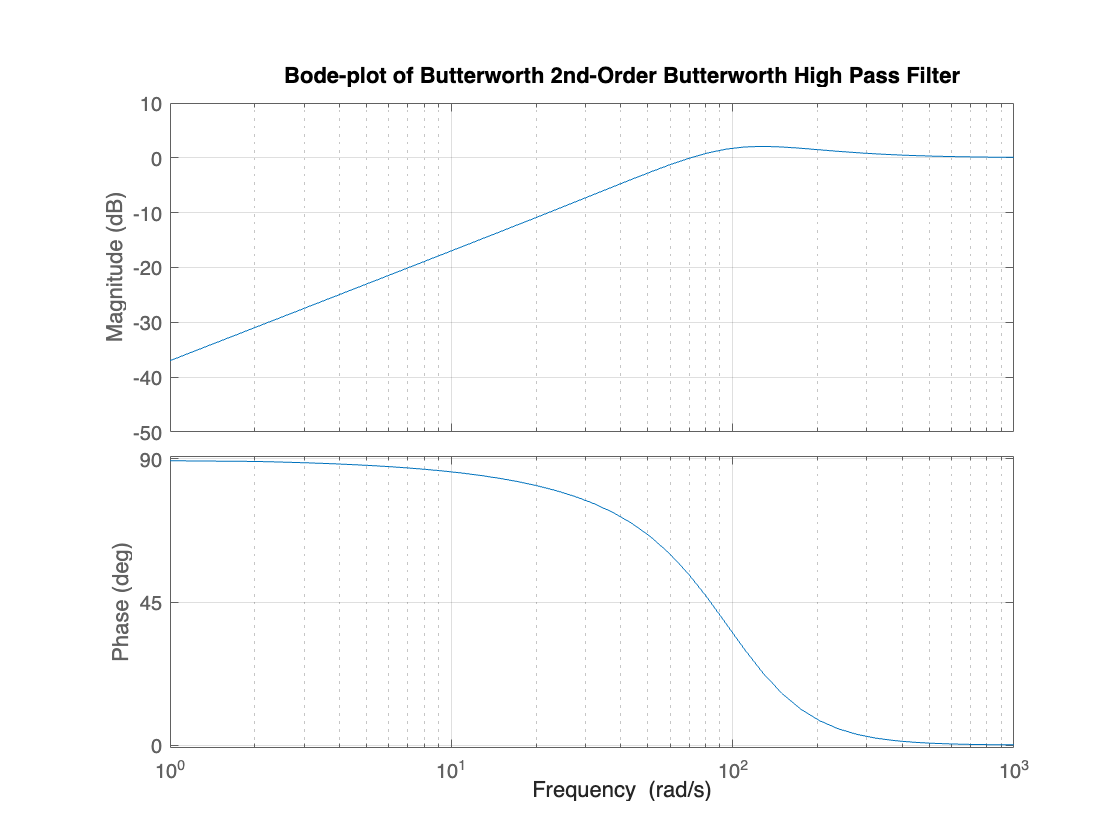

bode(Hhp)
grid
title('Bode-plot of Butterworth 2nd-Order Butterworth High Pass Filter')

### Magnitude frequency response

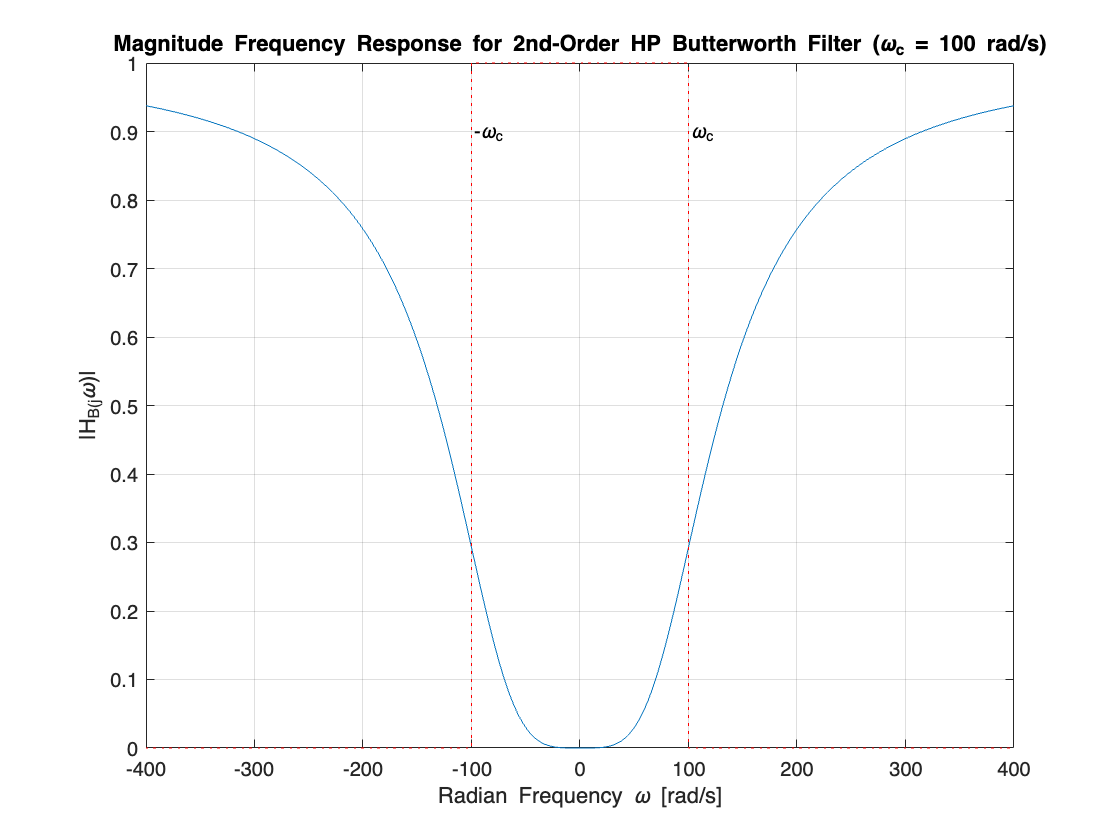

figure
w = -400:400;
plot(w,1-mHlp)
grid
ylabel('|H_B(j\omega)|')
title('Magnitude Frequency Response for 2nd-Order HP Butterworth Filter (\omega_c = 100 rad/s)')
xlabel('Radian Frequency \omega [rad/s]')
text(100,0.9,'\omega_c')
text(-100,0.9,'-\omega_c')
hold on
plot([-400,-100,-100,100,100,400],[0,0,1,1,0,0],'r:')
hold off